# Geometry from `polyshape`

This example shows how to create a polygonal geometry using the MATLAB `polyshape` function. Then use the triangulated representation of the geometry as an input mesh for the `geometryFromMesh` function.

Create and plot a [polyshape](docid:matlab_ref#mw_e828c4c3-eb67-4672-abbe-35077d4ada9b) object of a square with a hole.

t = pi/12:pi/12:2*pi;
% pgon = polyshape({[-0.5 -0.5 0.5 0.5], 0.25*cos(t)}, ...
%                  {[0.5 -0.5 -0.5 0.5], 0.25*sin(t)})
% pgon = polyshape({[-0.5 -0.5 0.5 0.5]}, ...
%                  {[0.5 -0.5 -0.5 0.5]})
pgon = polyshape({0.25*cos(t)}, ...
                 {0.25*sin(t)})

pgon =   polyshape with properties:

      Vertices: [24×2 double]
    NumRegions: 1
      NumHoles: 0


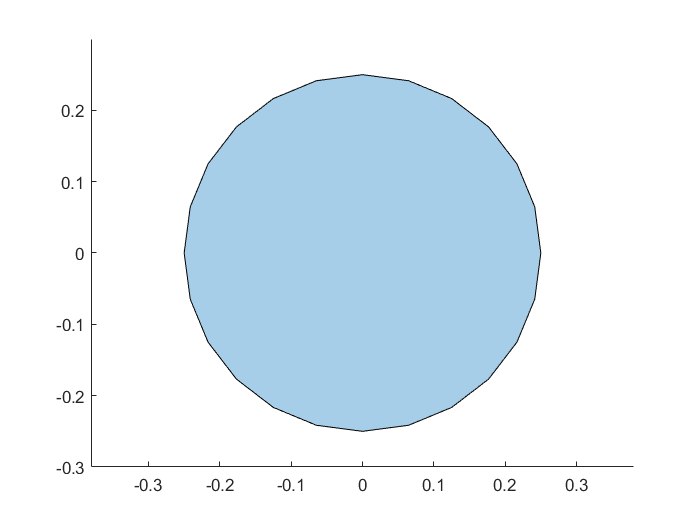


plot(pgon)
axis equal

Create a triangulation representation of this object.

tr = triangulation(pgon);

Create a PDE model.

model = createpde;

With the triangulation data as a mesh, use the `geometryFromMesh` function to create a geometry. Plot the geometry.

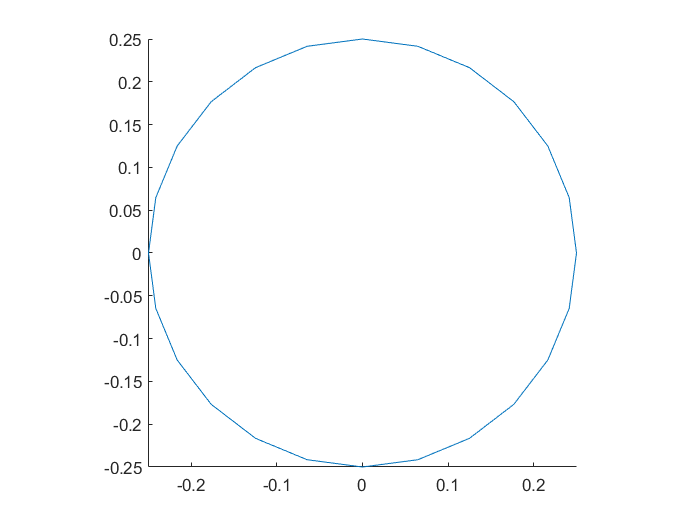

tnodes = tr.Points';
telements = tr.ConnectivityList';

geometryFromMesh(model,tnodes,telements);
pdegplot(model)

Plot the mesh.

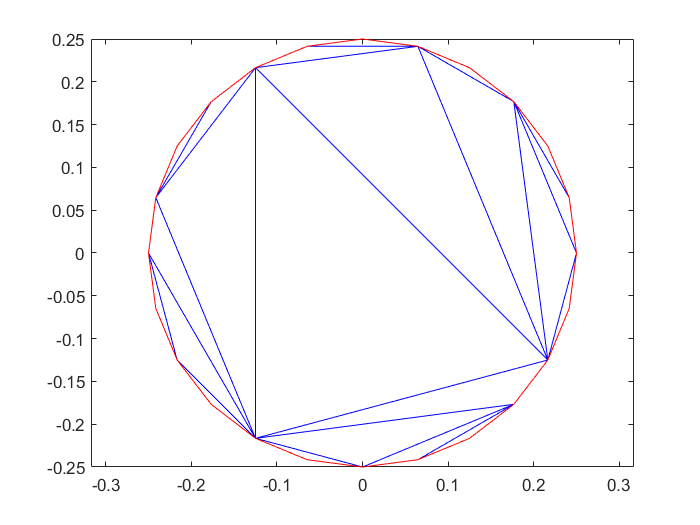

figure
pdemesh(model)

Because the triangulation data resulted in a low-quality mesh, generate a new finer mesh for further analysis.

Mesh1 = generateMesh(model)

Mesh1 =   FEMesh with properties:

             Nodes: [2×1132 double]
          Elements: [6×537 double]
    MaxElementSize: 0.0283
    MinElementSize: 0.0141
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


Plot the mesh.

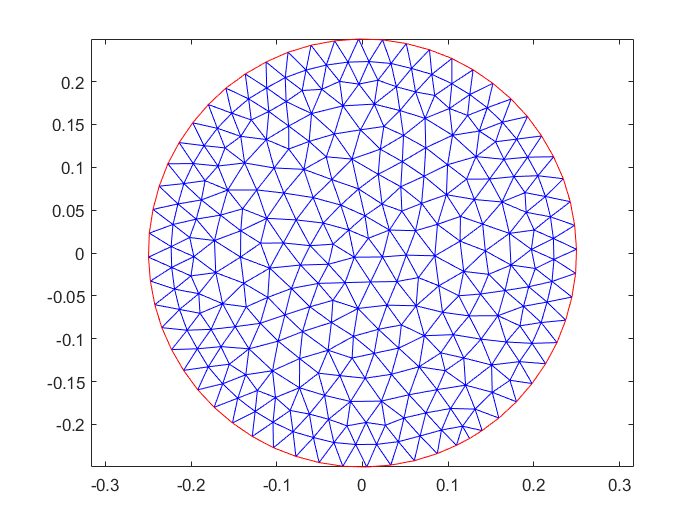

figure
pdemesh(model)

*Copyright 2012 The MathWorks, Inc.*

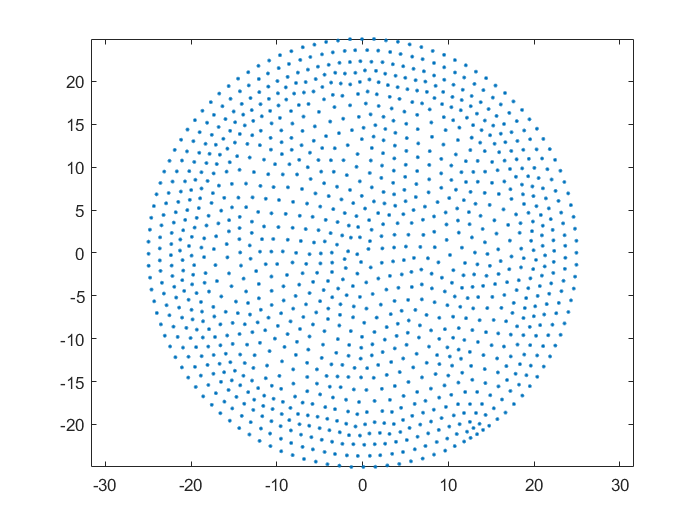

nodes1 = Mesh1.Nodes;
x0 = 100*nodes1(1,:);
y0 = 100*nodes1(2,:);

% writematrix([x0',y0'], 'initial_locations1.csv')
[theta0, r0] = cart2pol(x0,y0);

L = 2; % L = m*v cross r, v = r*d(theta)/d(t)
delta_t = 0.5;
figure
for iter = 1:1
    delta_theta = delta_t*L./r0;
    theta = theta0 + delta_theta;
    
    [x, y] = pol2cart(theta,r0);
    
    plot(x,y,'.')
%     hold on
%     voronoi(x,y)
%     hold off
    axis equal
    
    pause(0.1)
    drawnow
end

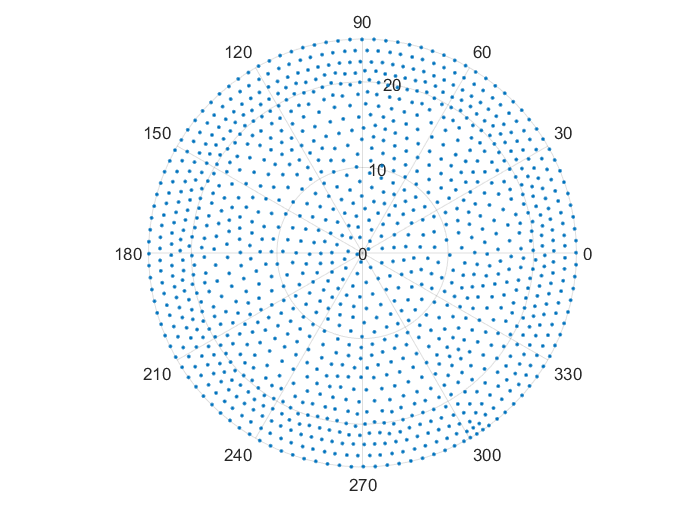


figure
polarscatter(theta,r0, '.')

% [x, y] = pol2cart(theta,r0);
% hold on
% voronoi(x,y)
% hold off